# Lab 2

### Gabriel Casciano, 500744078

## Part A

### A1

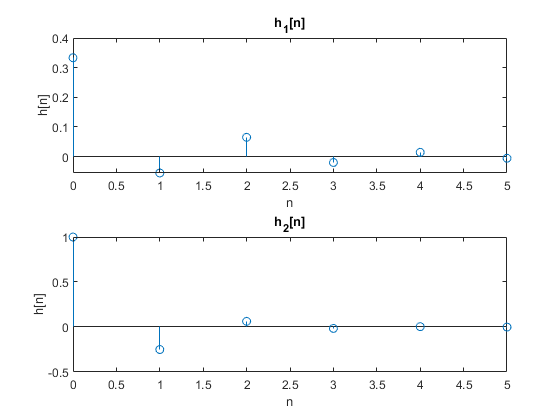

a_1 = [1, 1/6, -1/6];
b_1 = 1/3;

a_2 = [1, 1/4];
b_2 = [1];

delta = @(n) (n==0);

n = 0:5;

h_1 = filter(b_1, a_1, delta(n));
h_2 = filter(b_2, a_2, delta(n));

subplot(2,1,1);
stem(n, h_1);
title("h_{1}[n]")
ylabel("h[n]");
xlabel("n");

subplot(2,1,2);
stem(n, h_2);
title("h_{2}[n]")
ylabel("h[n]");
xlabel("n");

## Part B

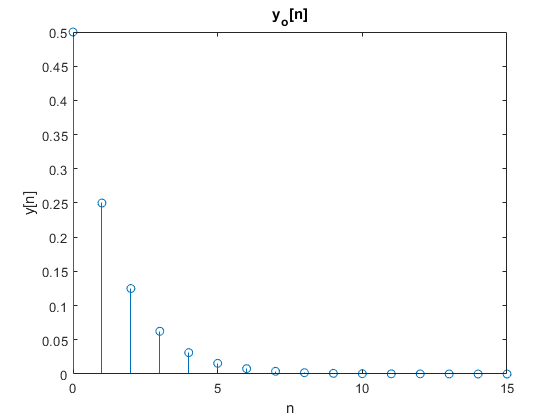

a = [1, -3/10, -1/10];
b = 2;
inc = [1, 2];

n = 0:15;

z = filtic(b, a, inc);
y_0 = filter(b, a, zeros(size(n)), z);

subplot(1,1,1);
stem(n, y_0);
title("y_{o}[n]")
ylabel("y[n]");
xlabel("n");

## Part C

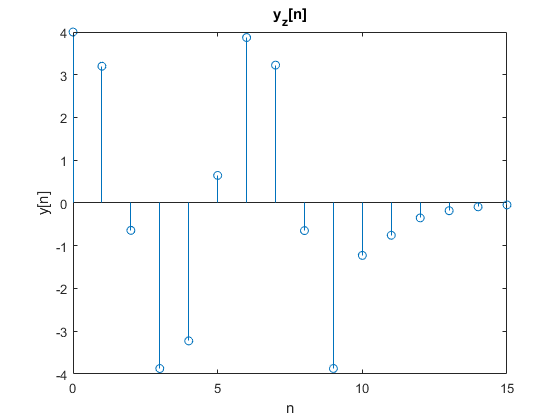

u = @(n) 1*(n>=0);
x = @(n) 2.*cos((2*pi.*n)/6).*(u(n) - u(n-10));

y_z = filter(b, a, x(n));

stem(n, y_z);
title("y_{z}[n]")
ylabel("y[n]");
xlabel("n");

## Part D

### D1

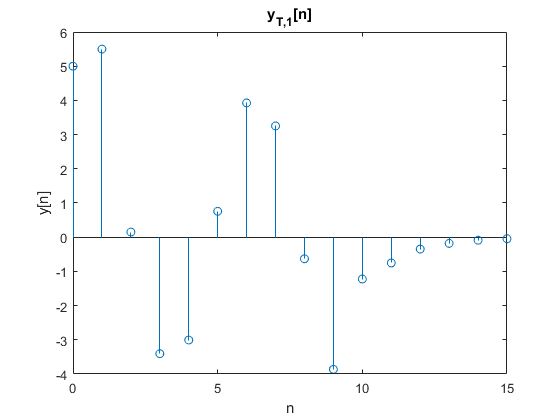

y_t_1 = filter(b, a, x(n), inc);

stem(n, y_t_1);
title("y_{T,1}[n]")
ylabel("y[n]");
xlabel("n");

### D2

Yes, the total response is the combination of the zero-input (free) and zero-state, initial conditions (forced) response. 

## Part E

### E1

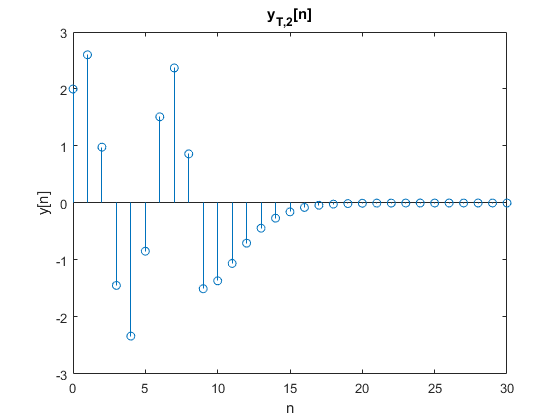

n_con = 0:30;
y_t_2 = conv(y_0, y_z);

stem(n_con, y_t_2);
title("y_{T,2}[n]")
ylabel("y[n]");
xlabel("n");

### E2

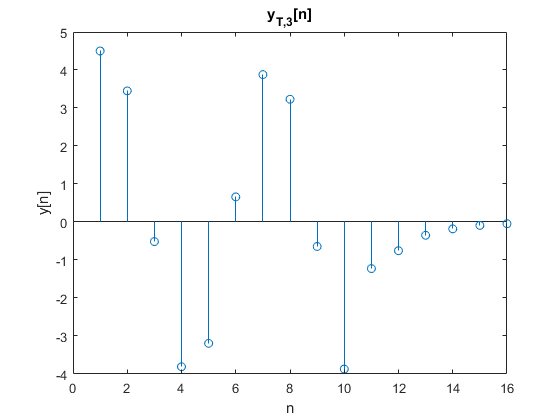

y_t_3 = y_0 + y_z;

stem(y_t_3);
title("y_{T,3}[n]")
ylabel("y[n]");
xlabel("n");

Does matc part c

### E3

Yes, this system is asymptotically stable, since the total response returns to a value of 0

## Part F

### F1

### F2

N = 45;
[a, b] = moving_average_filter(N);

### F3

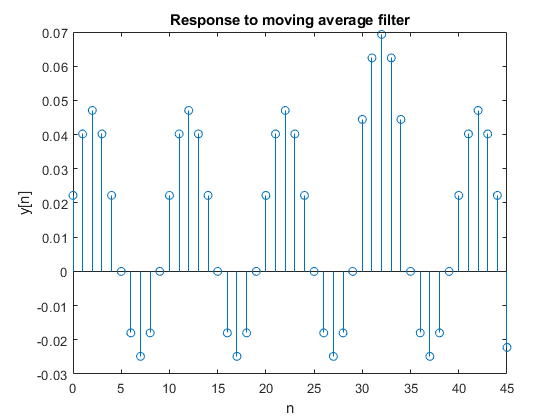

n = 0:N;
delta = @(n) (n==0);
x = @(n) cos((pi*n)/5)+delta(n-30)-delta(n-35);

y = filter(b, a, x(n));

stem(n, y);
title("Response to moving average filter")
ylabel("y[n]");
xlabel("n");

function [a,b] = moving_average_filter(N)
    a = 1;
    b = (1/N)*ones(1,N);
end 